%Plot the observed data in dBm vs. log10(r / r0), 
% where r is the distance between Tx and Rx. 
%On the samegraph plot the free-space model, 
% choosing P0 to give a reasonable fit to the x ≤ 0 data
% (where diffraction is not yet a big effect). 
% You can “eyeball” the fit, i.e., you don’t need to
%do a numerical minimization. 
%Part one
data_dBm = [-39 -37 -36 -41 -45 -43 -52 -42 -52 -62 -64 ...
    -60 -72 -64 -72 -68 -62 -79];
yr = 1.745; %in m
yt = 15.2; %in m
xt = 4.215; %in m
r0 = 16.959; %yt + yr%in m
rAdjacent = [0 2 4 6 8 10 12 14 16 18 20 22 24 26 28 ...
    30 32 34]; %in ft
conv = .3048;
r_m = zeros(1,18);
for j = 1:18
    r_m(j) = rAdjacent(j)*conv;
end
r = zeros(1,18);
for i = 1:18
    r(i) = sqrt(r_m(i)^2 + r0^2);
end
r; %For checking
roverr0 = log10(r/r0)

roverr0 =          0    0.0003    0.0011    0.0025    0.0044    0.0069    0.0099    0.0133    0.0173    0.0216    0.0264    0.0315    0.0371    0.0429    0.0490    0.0554    0.0621    0.0689


%Against wall , plot this point
r_LOS = sqrt(r0^2 + (4.215)^2)

r_LOS = 17.4750

r_LOS_dB = log10(r_LOS/r0)

r_LOS_dB = 0.0130

%Free Space Model
P0 = -43;
n= 3;
Pr_fs = P0 - 10*n*roverr0

Pr_fs =   -43.0000  -43.0084  -43.0336  -43.0753  -43.1333  -43.2071  -43.2962  -43.3999  -43.5176  -43.6484  -43.7916  -43.9463  -44.1116  -44.2866  -44.4706  -44.6625  -44.8616  -45.0670


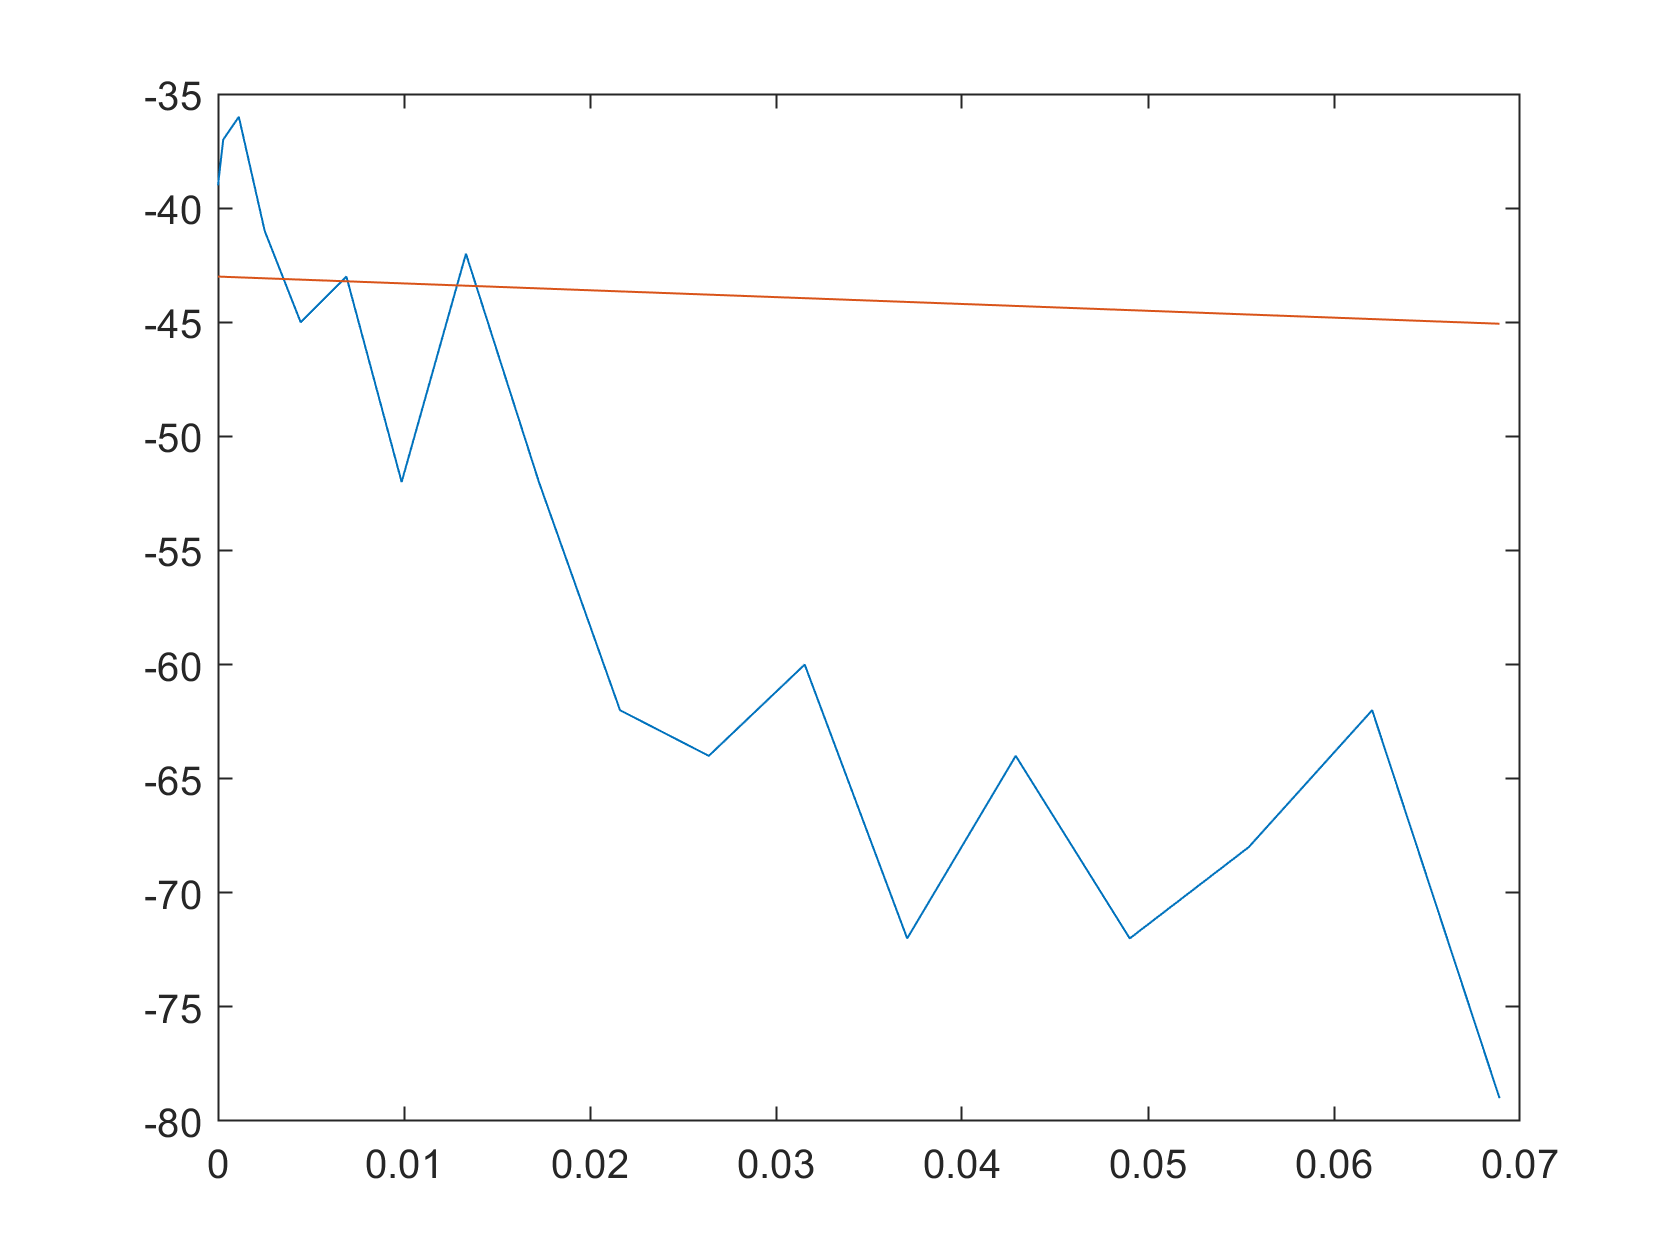

%Plot over range
plot(roverr0, data_dBm, roverr0, Pr_fs)

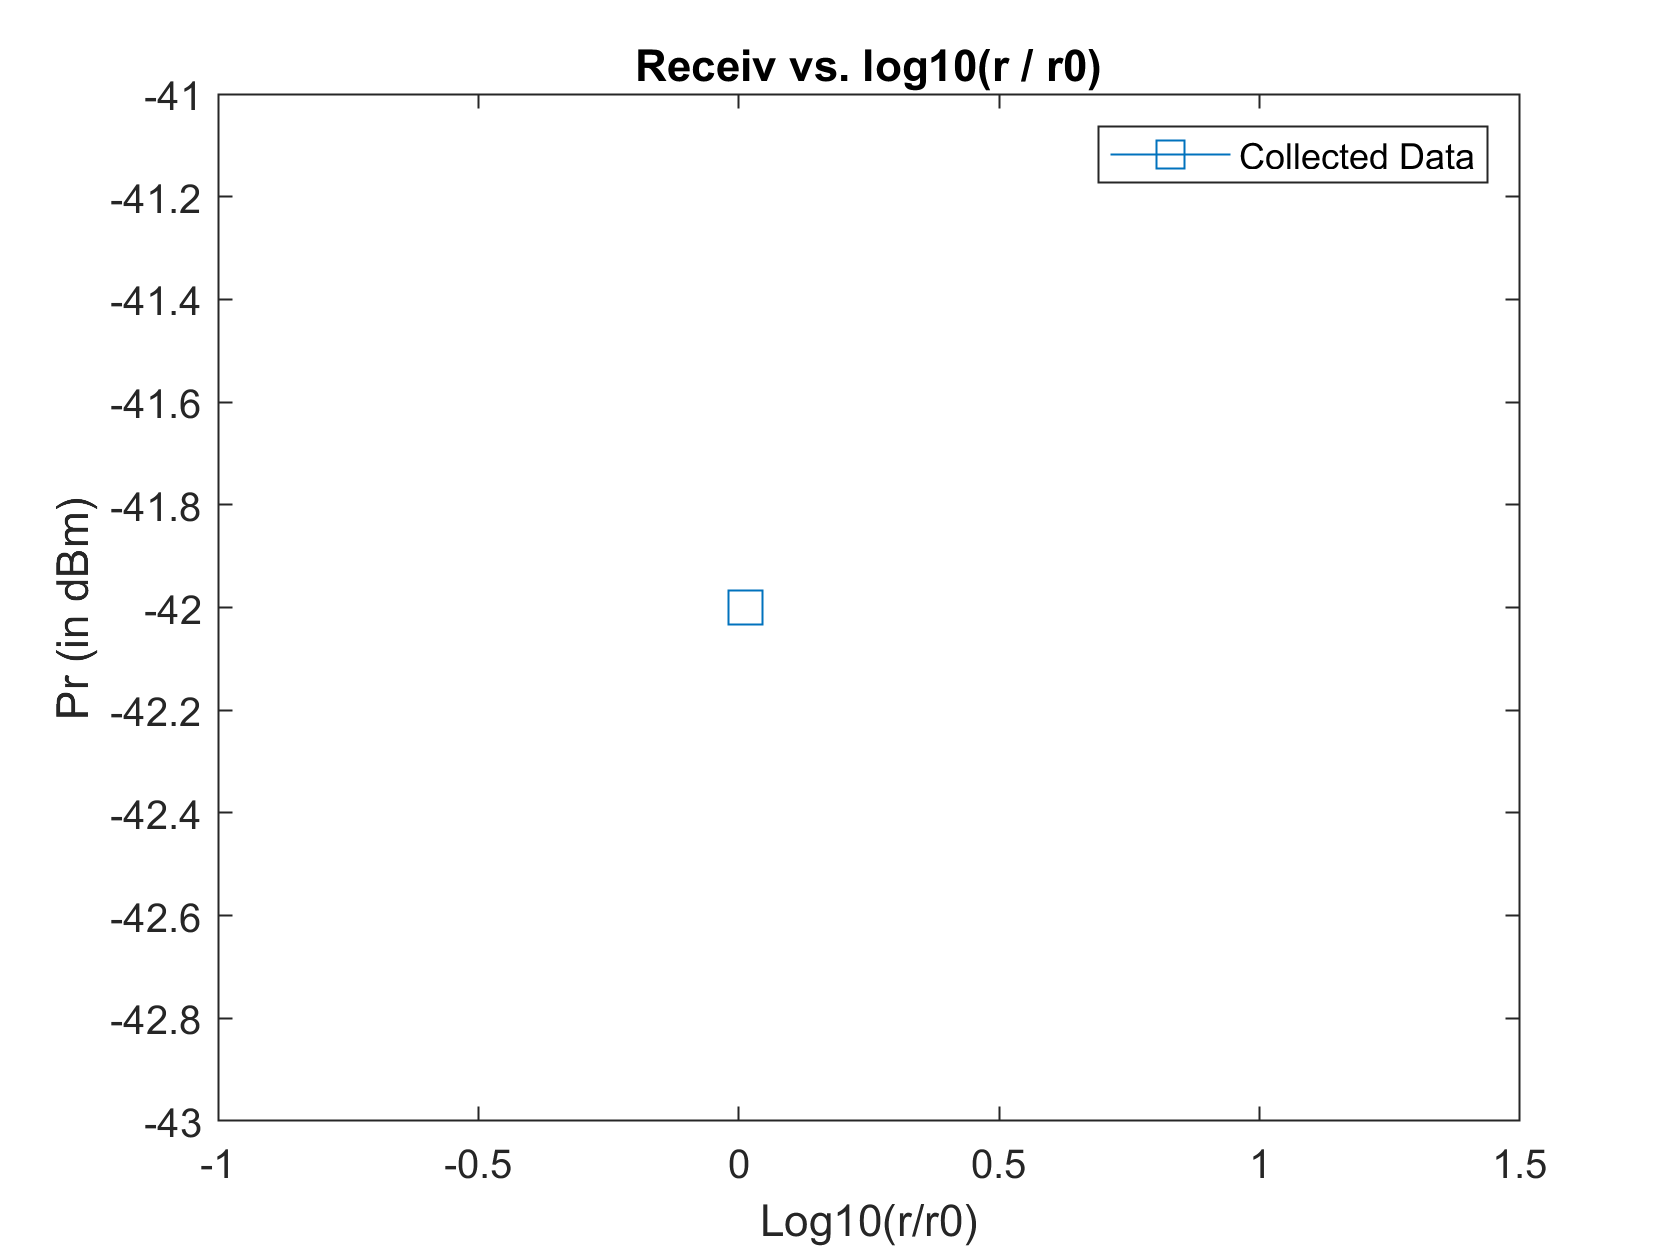

%This is to plot the point on the graph
%I realized when calculating by r_LOS_dB
%That this value is similar to our 8th data point 
%This code I found on a MATLAB forum, all credit
%to them
PointsPerPixels = 72/get(0,'ScreenPixelsPerInch');
plot(roverr0(8), data_dBm(8),'Marker','s','MarkerSize', 15 * PointsPerPixels)
xlabel('Log10(r/r0)')
ylabel('Pr (in dBm)')
title('Receiv vs. log10(r / r0)')
legend('Collected Data', 'Free Space Model', 'Line of sight lost')


%Part 2
%Calculate the diffraction gain for every point of 
% observation. Plot the observed data and
% the diffraction model
Gd = zeros(1,18); 
Pr_diff = zeros(1,18); 
frequency = 915*10^6;
c = 3*10^8;
n = 3;
wavel = c/frequency;
for i =1:length(data_dBm)
    %need to calculate u in this thing 
    %Tyler Dickey helped me with the approach 
    %I will attach my hand drawn diagrams 
    %to demonstrate my idea 
    if r_m(i) < 4.215
        Gd(i) = 0; 
    else
    a = yr*r_m(i)/(r0);
    phi = atand(yr/(r_m(i)-xt));
    psi = atand(a/yr);
    theta = 90-psi-phi;
    b = sqrt(yr^2 + (r_m(i) - xt)^2);
    r2 = b*cosd(theta);
    h = b*sind(theta);
    r1 = sqrt(r0^2 + r_m(i)^2) - r2;
    u = h*sqrt((2/wavel)*((r1+r2)/(r1*r2)));
    if u <= -1
        Gd(i) = 0;
    elseif u >= 1
        Gd(i) = 20*log10(1/(sqrt(2)*pi*u));
    else
        Gd(i) = -6.5*(u+1);
    end
    end
   P0 = -37;
   Pr_diff(i) = P0 - 10*n*roverr0(i) + Gd(i);
end

% P0 = -10;
% for j = 1:18
% 
% end

%for checking
Gd

Gd =          0         0         0         0         0         0         0   -1.6445   -8.4137  -14.7713  -19.2538  -21.8893  -23.6819  -24.9954  -26.0044  -26.8059  -27.4593  -28.0032


Pr_diff

Pr_diff =   -37.0000  -37.0084  -37.0336  -37.0753  -37.1333  -37.2071  -37.2962  -39.0444  -45.9313  -52.4197  -57.0454  -59.8356  -61.7935  -63.2821  -64.4750  -65.4684  -66.3209  -67.0702


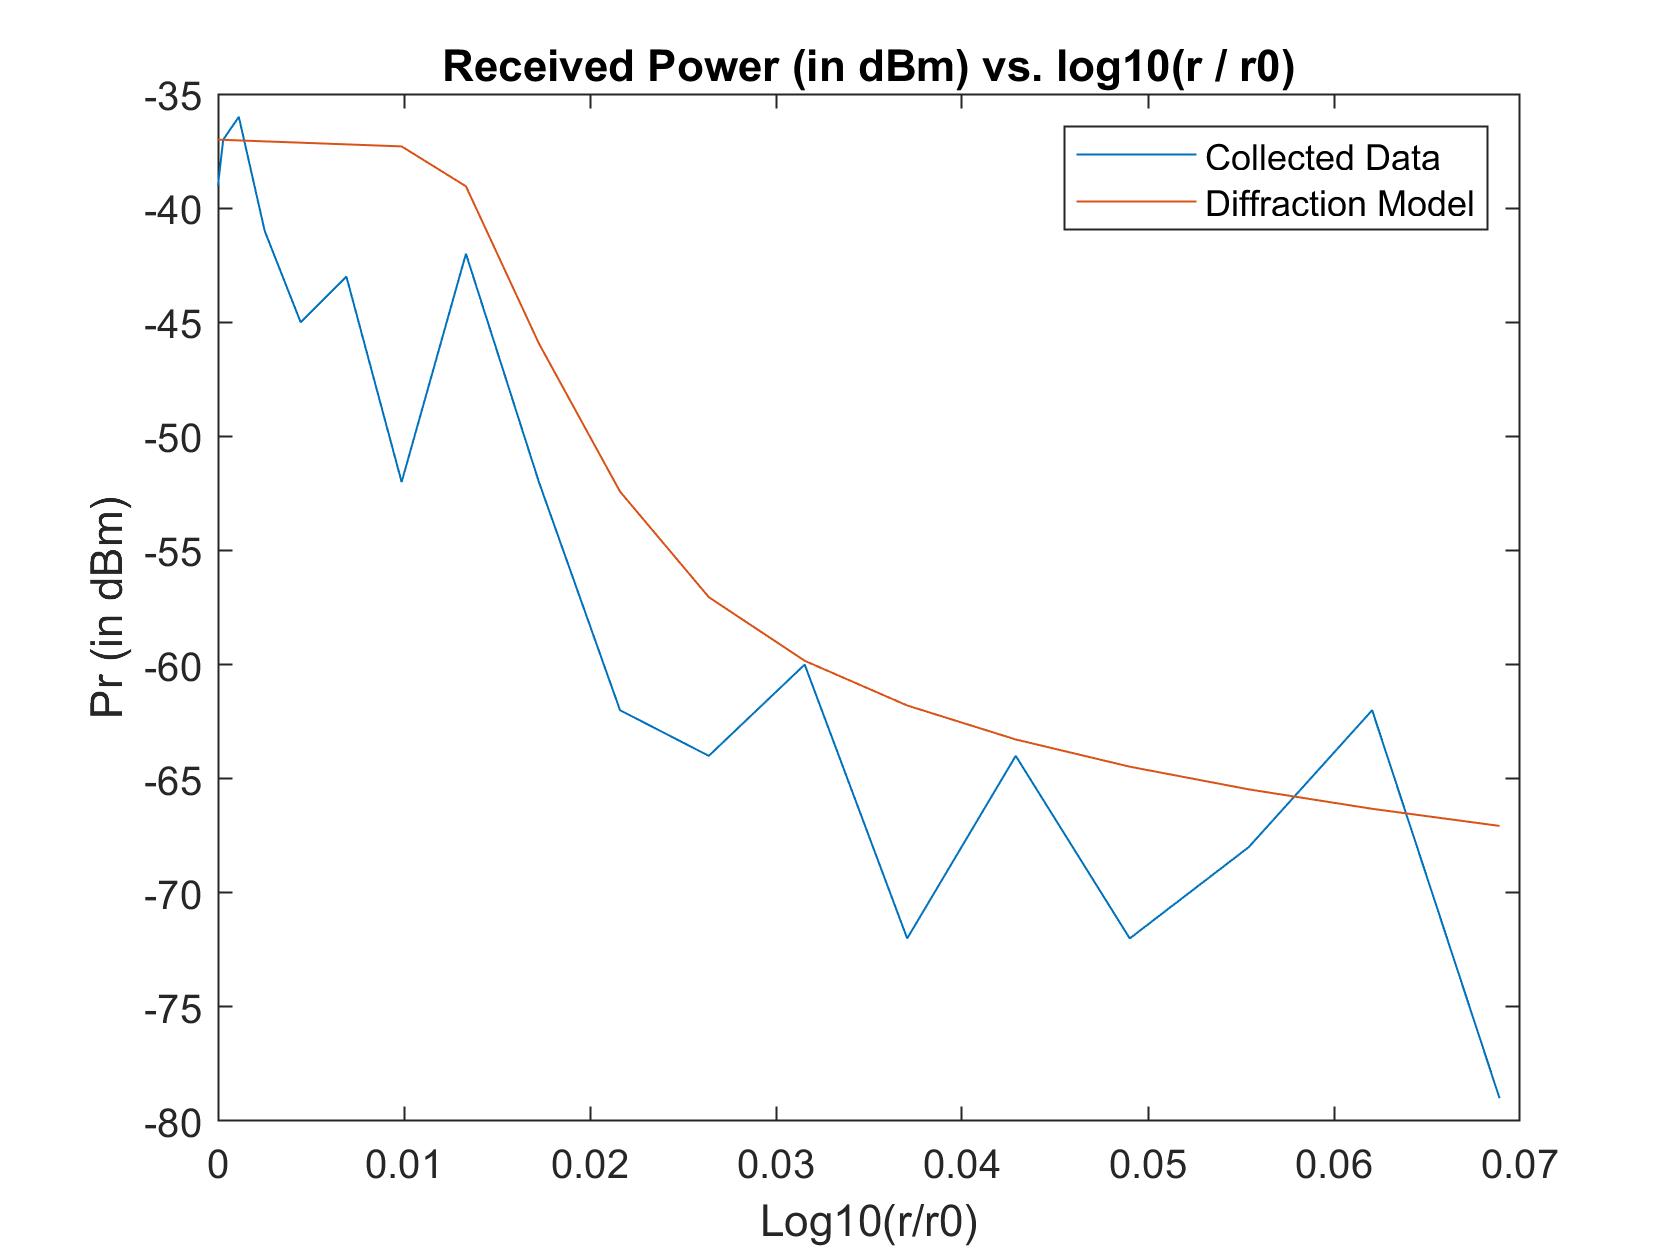

%plot the diffraction model
plot(roverr0, data_dBm, roverr0,Pr_diff)
xlabel('Log10(r/r0)')
ylabel('Pr (in dBm)')
title('Received Power (in dBm) vs. log10(r / r0)')
legend('Collected Data', 'Diffraction Model')

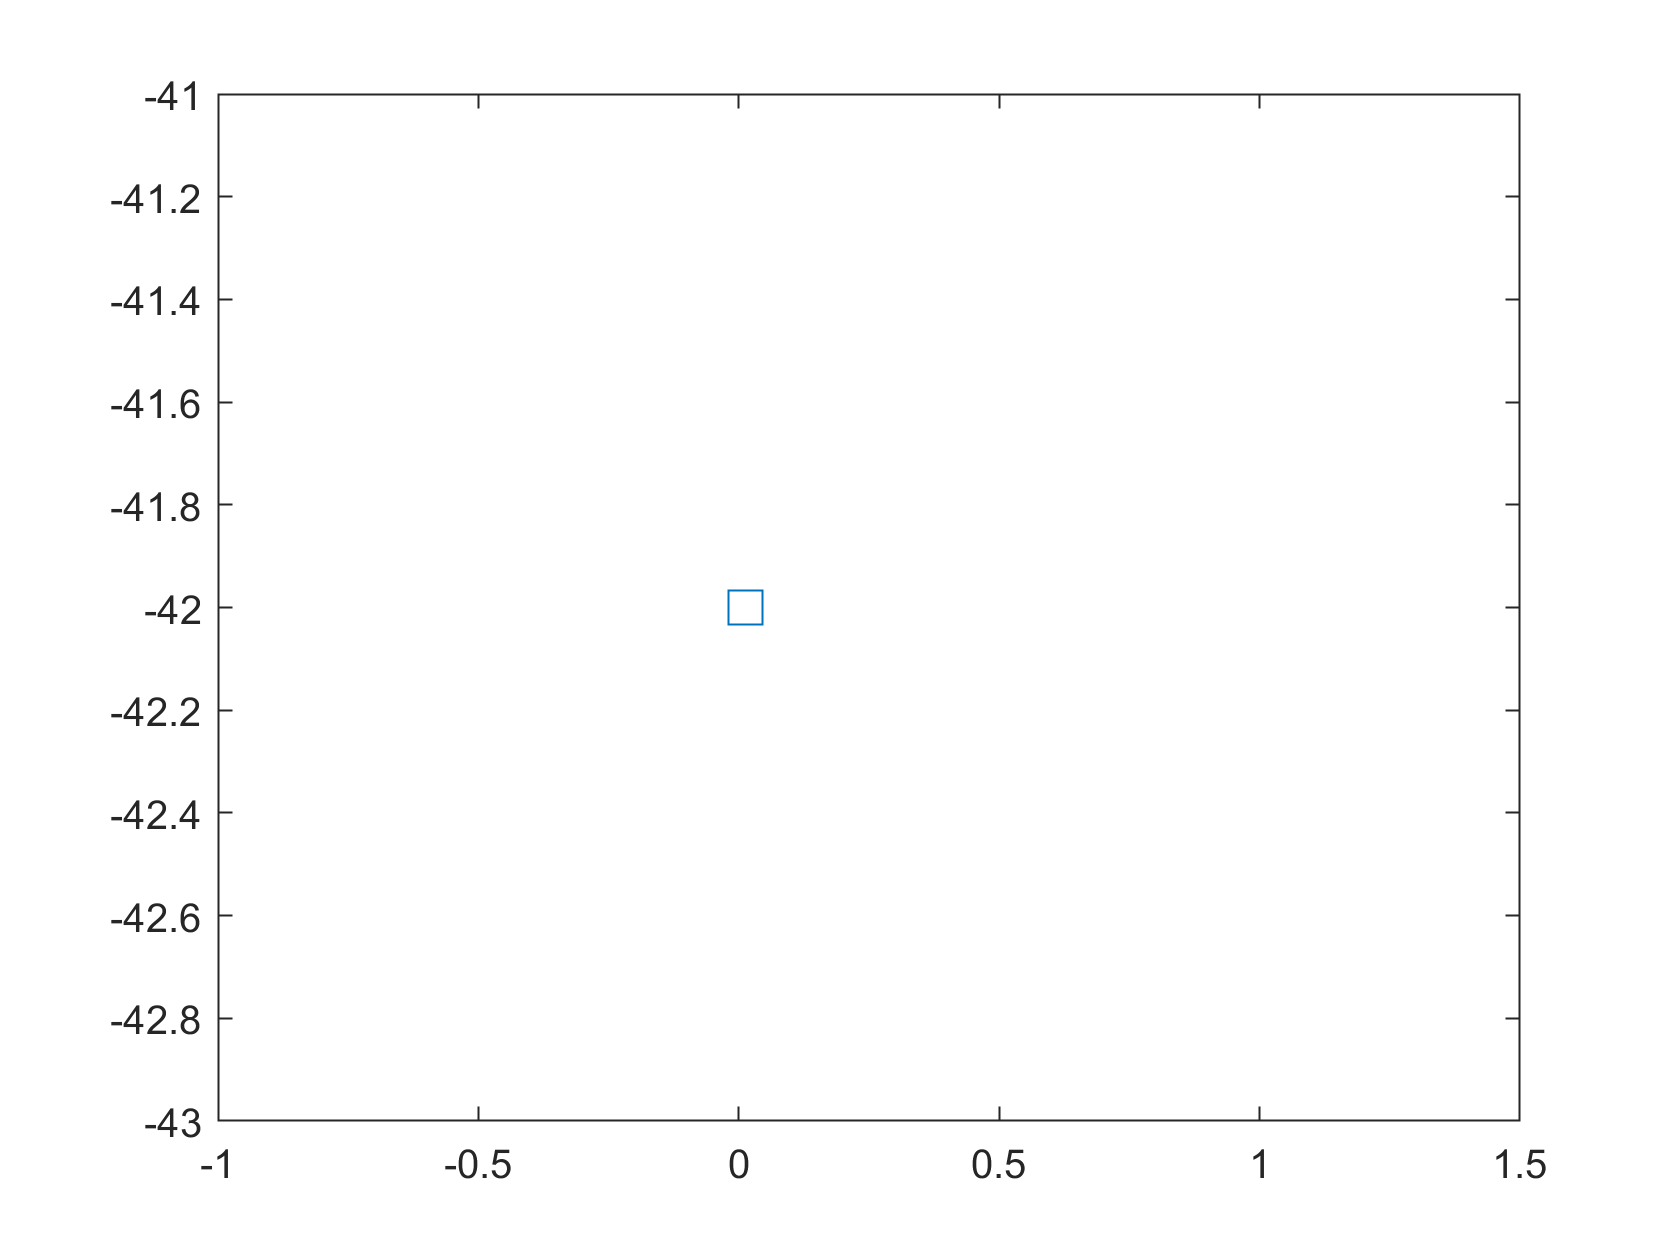

PointsPerPixels = 72/get(0,'ScreenPixelsPerInch');
plot(roverr0(8), data_dBm(8),'Marker','s','MarkerSize', 15 * PointsPerPixels)




%PART 3
Gd_3 = zeros(1,18); 
Pr_difftx = zeros(1,18);
Pr_difftxGD = zeros(1,18);
Pr_difftxAF = zeros(1,18);
AF = zeros(1,18);
frequency = 915*10^6;
c = 3*10^8;
n = 3;
P0 = -39;
wavel = c/frequency;
for i =1:length(data_dBm)
    %need to calculate u in this thing 
    %Tyler Dickey helped me with the approach 
    %I will attach my hand drawn diagrams 
    %to demonstrate my idea 
    if r_m(i) < 4.215
        Gd_3(i) = 0;
        AF(i) = 0;
        %Pr_difftx(i) = P0 - 10*n*roverr0(i);
    else
    a = yr*r_m(i)/(r0);
    phi = atand(yr/(r_m(i)-xt));
    psi = atand(a/yr);
    theta = 90-psi-phi;
    b = sqrt(yr^2 + (r_m(i) - xt)^2);
    r2 = b*cosd(theta);
    h = b*sind(theta);
    r1 = sqrt(r0^2 + r_m(i)^2) - r2;
    u = h*sqrt((2/wavel)*((r1+r2)/(r1*r2)));
    if u <= -1
        Gd_3(i) = 0;
        AF(i) = 0;
    elseif u >= 1
        Gd_3(i) = 20*log10(1/(sqrt(2)*pi*u));
        AF(i) = 35; 
    else
        Gd_3(i) = -6.5*(u+1);
        if u<0
            AF(i) = 0; 
        else
            AF(i) = 30;
        end
    end
    end
end

%I tried putting it in the above loop but it wasn't working
%Suggested that I move it into another loop, to simplify
for j = 1:18
    if r_m < 4.216
        Gd_3(j) = 0; 
        Pr_difftx(j) = P0 - 10*n*roverr0(j);
    else
    Pr_difftxGD(j) = P0 - 10*n*roverr0(j) + Gd_3(j);
    Pr_difftxAF(j) = P0 - 10*n*roverr0(j) - AF(j);
    Pr_difftx(j) = 10*log10(10^(Pr_difftxGD(j)/10) + 10^(Pr_difftxAF(j)/10)); 
    end
    
end
%for checking
Gd_3

Gd_3 =          0         0         0         0         0         0         0   -1.6445   -8.4137  -14.7713  -19.2538  -21.8893  -23.6819  -24.9954  -26.0044  -26.8059  -27.4593  -28.0032


Pr_difftx

Pr_difftx =   -35.9897  -35.9981  -36.0233  -36.0650  -36.1230  -36.1968  -36.2859  -37.1345  -47.9013  -54.3787  -58.9312  -61.6285  -63.4841  -64.8686  -65.9595  -66.8555  -67.6162  -68.2796


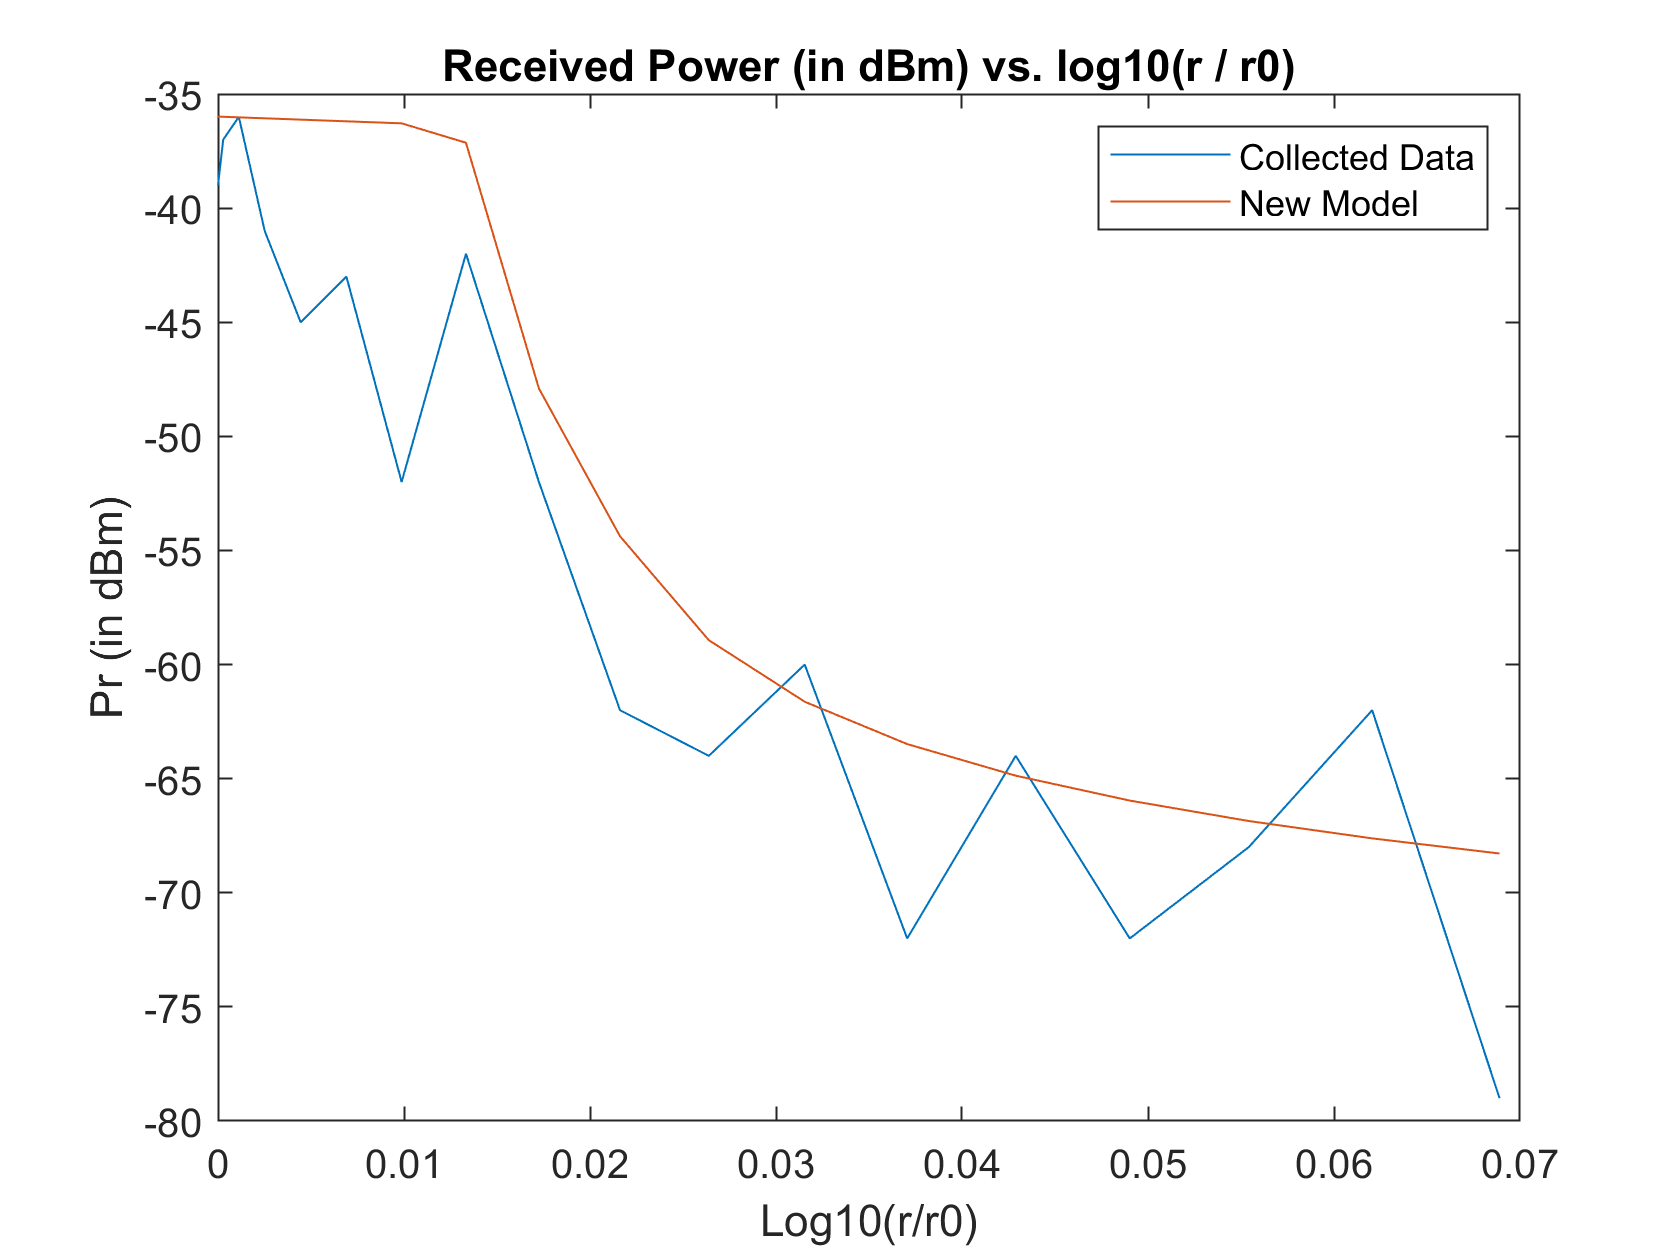

%plot the model 
plot(roverr0, data_dBm, roverr0,Pr_difftx)
xlabel('Log10(r/r0)')
ylabel('Pr (in dBm)')
title('Received Power (in dBm) vs. log10(r / r0)')
legend('Collected Data', 'New Model')

PointsPerPixels = 72/get(0,'ScreenPixelsPerInch');
plot(roverr0(8), data_dBm(8),'Marker','s','MarkerSize', 15 * PointsPerPixels)